# **Deliverable 3: Dynamics and Control**

**Author: Ilyass Afkir**

## 1) ***Obtain the dynamic model (inertia and Coriolis matrices and the friction and gravitational terms) and check the correctness by also modeling it using the Robotics Toolbox.***

Definiton of different variables. 

mdl_puma560;
%plot(p560,[0 0 0 0 0 0])
%teach(p560)
l=p560.links(2).a;
m=p560.links(2).m;
r=0.05;


%load the predefines two-link manipulator in the xz plane
%mdl_twolink
L(1) = Link([0 0 l 0]);
L(2) = Link([0 0 l 0]);
L(3) = Link([0 0 l 0]);
threelink = SerialLink(L, 'name', 'three-link');


%joint variables
syms qi q1 q2 q3 'real'
%link lengths
syms ai a1 a2 a3 'real'
%link offsets
syms di 'real'
%link twists
syms alphai 'real'
%lengths    
syms l1 l2 l3 'real'
%masses
syms m1 m2 m3 'real'
%Inertia
syms Ixx1 Iyy1 Izz1 Ixy1 Ixz1 Iyz1 Ixx2 Iyy2 Izz2 Ixy2 Ixz2 Iyz2 Ixx3 Iyy3 Izz3 Ixy3 Ixz3 Iyz3 'real'
Il11 = [Ixx1 -Ixy1 -Ixz1; -Ixy1 Iyy1 -Iyz1; -Ixz1 -Iyz1 Izz1];
Il22 = [Ixx2 -Ixy2 -Ixz2; -Ixy2 Iyy2 -Iyz2; -Ixz2 -Iyz2 Izz2];
Il33 = [Ixx3 -Ixy3 -Ixz3; -Ixy3 Iyy3 -Iyz3; -Ixz3 -Iyz3 Izz3];
%inertia matrix
syms b11 b12 b21 b22  'real'
%velocities, accelerations, gravity and torques
syms qdot1 qdot2 qdot3 qdotdot1 qdotdot2 qdotdot3 'real'
syms g tau1 tau2 tau3 'real'
%friction
syms Bm1 Bm2 Bm3 'real'
%gear ratios
syms Gear1 Gear2 Gear3 'real'


%A matrices
A01i = [cos(qi) -sin(qi)*cos(alphai)  sin(qi)*sin(alphai) ai*cos(qi);...
       sin(qi)  cos(qi)*cos(alphai) -cos(qi)*sin(alphai) ai*sin(qi);...
          0     sin(alphai)          cos(alphai)         di;...
          0    0     0    1];
    
A01 = subs(A01i,{ai,di,alphai,qi},{ a1, 0, 0, q1});
A12 = subs(A01i,{ai,di,alphai,qi},{ a2, 0, 0, q2});
A23 = subs(A01i,{ai,di,alphai,qi},{ a3, 0, 0, q3});

Here we are computing the Direct Kinematics and the Geometric Jacobian.

% direct kinematics
A03  = A01*A12*A23;

% Geometric Jacobian
% compute the origins and z vectors of the frames
p0 = [0 0 0 1]';
p1 = A01*p0;
p2 = A01*A12*p0;
p3 = A01*A12*A23*p0;
z0 = [0 0 1]';
z1 = A01(1:3,1:3)*z0;
z2 = A01(1:3,1:3)*A12(1:3,1:3)*z0;
J = [ cross(z0,p3(1:3)-p0(1:3)), cross(z1,p3(1:3)-p1(1:3)), cross(z2,p3(1:3)-p2(1:3));
            z0   z1  z2];   
J = simplify(J)

$$J = \begin{array}{l} \left(\begin{array}{ccc} -a_{2}\,\sin\left(q_{1}+q_{2}\right)-a_{1}\,\sin\left(q_{1}\right)-\sigma_{1} & -a_{2}\,\sin\left(q_{1}+q_{2}\right)-\sigma_{1} & -\sigma_{1}\\ a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)+\sigma_{2} & a_{2}\,\cos\left(q_{1}+q_{2}\right)+\sigma_{2} & \sigma_{2}\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=a_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

Here we are computing the inertia matrice

%define the link lengths
vsa1 = l; vsa2 = l; vsa3 = l;
%define the masses 
vm1 = m; vm2 = m; vm3=m;

%set link masses
threelink.links(1).m = vm1;
threelink.links(2).m = vm2;
threelink.links(3).m = vm3;

%define the inertia
vIzz1 = (1/12)*vm1*vsa1^2+0.25*vm1*r^2; 
vIzz2 = (1/12)*vm2*vsa2^2+0.25*vm2*r^2;
vIzz3 = (1/12)*vm3*vsa3^2+0.25*vm3*r^2;

%set link inertias 
threelink.links(1).I = zeros(3);
threelink.links(1).I(3,3) = vIzz1;
threelink.links(2).I = zeros(3);
threelink.links(2).I(3,3) = vIzz2;
threelink.links(3).I = zeros(3);
threelink.links(3).I(3,3) = vIzz3;

%define the friction coefficient
Bm=0.000817; %from dyn
vBm1 = Bm; vBm2 = Bm; vBm3 = Bm;

%set the friction, scaled up by G^2
threelink.links(1).B = vBm1; 
threelink.links(2).B = vBm2;
threelink.links(3).B = vBm3;

%define the gear ratio 
G=107.8;
vGear1 = G; vGear2 = G; vGear3 = G;
%set the gear ratios
threelink.links(1).G = vGear1;
threelink.links(2).G = vGear2;
threelink.links(3).G = vGear3;

%define Tr
threelink.links(1).Tc=[0.126,-0.071];
threelink.links(2).Tc=[0.126,-0.071];
threelink.links(3).Tc=[0.126,-0.071];

%define motor inertia
threelink.links(1).Jm=0;
threelink.links(2).Jm=0;
threelink.links(3).Jm=0;
%set CoM
CoM=[r/2 0 0]; %center of masses
threelink.links(1).r = CoM;
threelink.links(2).r = CoM;
threelink.links(3).r = CoM;
%set the gravity
threelink.gravity = [0 -9.81 0];

%Inertia matrice 
A01_l = subs(A01i,{ai,di,alphai,qi},{ vsa1, 0, 0, q1});
A12_l = subs(A01i,{ai,di,alphai,qi},{ vsa2, 0, 0, q2});
A23_l = subs(A01i,{ai,di,alphai,qi},{ vsa3, 0, 0, q3});
pl1 = A01_l*p0;
pl2 = A01_l*A12_l*p0;
pl3 = A01_l*A12_l*A23_l*p0;

JP_l1 = [cross(z0,pl1(1:3)-p0(1:3)), [0 0 0]', [0 0 0]'];
JP_l2 = [cross(z0,pl2(1:3)-p0(1:3)), cross(z1,pl2(1:3)-p1(1:3)), [0 0 0]'];
JP_l3 = [cross(z0,pl3(1:3)-p0(1:3)), cross(z1,pl3(1:3)-p1(1:3)), cross(z2,pl3(1:3)-p2(1:3))];
Jtheta_l1 = [z0 [0 0 0]' [0 0 0]'];
Jtheta_l2 = [z0 z1 [0 0 0]'];
Jtheta_l3 = [z0 z1 z2];

B1 = m1*JP_l1'*JP_l1;
B2 = m2*JP_l2'*JP_l2;
B3 = m3*JP_l3'*JP_l3;

R1 = A01(1:3,1:3);
vIl11 = subs(Il11,{Ixx1 Iyy1 Ixy1 Ixz1 Iyz1},{0 0 0 0 0});
Il1 = R1*vIl11*R1';

R2 = A01(1:3,1:3)*A12(1:3,1:3);
vIl22 = subs(Il22,{Ixx2 Iyy2 Ixy2 Ixz2 Iyz2},{0 0 0 0 0});
Il2 = R2*vIl22*R2';

R3 = A01(1:3,1:3)*A12(1:3,1:3)*A23(1:3,1:3);
vIl33 = subs(Il33,{Ixx2 Iyy2 Ixy2 Ixz2 Iyz2},{0 0 0 0 0});
Il3 = R3*vIl33*R3';

B4 = Jtheta_l1'*Il1*Jtheta_l1;
B5 = Jtheta_l2'*Il2*Jtheta_l2;
B6 = Jtheta_l3'*Il3*Jtheta_l3;

B = simplify(B1+B2+B3+B4+B5+B6)

% define joint velocities
qa=[pi/3 pi/3 pi/3];

% calculate inertia
vB = double(subs(B,{m1 l1 m2 l2 m3 l3 q1 q2 q3 a1 a2 a3 Izz1 Izz2 Izz3},{vm1 vsa1 vm2 vsa2 vm3 vsa3 qa(1) qa(2) qa(3) vsa1 vsa2 vsa3 vIzz1 vIzz2 vIzz3}))

vB =    26.7977   15.1616    3.5255
   15.1616   13.5395    5.1476
    3.5255    5.1476    3.5255


threelink.inertia([pi/3 pi/3 pi/3])

ans =    28.1452   16.1225    3.9120
   16.1225   14.5004    5.6281
    3.9120    5.6281    3.9120


Here the Coriolis matrix is calculated.

%% CORIOLIS MATRIX

b11 = B(1,1); b12 = B(1,2); b13 = B(1,3);
b21 = B(2,1); b22 = B(2,2); b23 = B(2,3);
b31 = B(3,1); b32 = B(3,2); b33 = B(3,3);


c111 = cijk(b11, b11, b11, q1, q1, q1);
c112 = cijk(b11, b12, b12, q1, q1, q2);
c113 = cijk(b11, b13, b13, q1, q1, q3);

c121 = c112;
c122 = cijk(b12, b12, b22, q1, q2, q2);
c123= cijk(b12,b13,b23,q1,q2,q3);

c131=cijk(b13,b11,b31,q1,q3,q1);
c132=cijk(b13,b12,b32,q1,q3,q2);
c133=cijk(b13,b13,b33,q1,q3,q3);

c211 = cijk(b21, b21, b11, q2, q1, q1);
c212 = cijk(b21, b22, b12, q2, q1, q2);
c213= cijk(b21,b23,b13,q2,q1,q3);
c221 = c212;
c222 = cijk(b22, b22, b22, q2, q2, q2);
c223= cijk(b22,b23,b23,q2,q2,q3);

c231=cijk(b23,b21,b31,q2,q3,q1);
c232=cijk(b23,b22,b32,q2,q3,q2);
c233=cijk(b23,b23,b33,q2,q3,q3);

c311=cijk(b31,b31,b11,q3,q1,q1);
c312=cijk(b31,b32,b12,q3,q1,q2);
c313=cijk(b31,b33,b13,q3,q1,q3);
c321=cijk(b32,b31,b21,q3,q2,q1);
c322=cijk(b32,b32,b22,q3,q2,q2);
c323=cijk(b32,b33,b23,q3,q2,q3);
c331=cijk(b33,b31,b31,q3,q3,q1);
c332=cijk(b33,b32,b32,q3,q3,q2);
c333=cijk(b33,b33,b33,q3,q3,q3);

c11 = c111*qdot1+c112*qdot2+c113*qdot3;
c12 = c121*qdot1+c122*qdot2+c123*qdot3;
c21 = c211*qdot1+c212*qdot2+c213*qdot3;
c22 = c221*qdot1+c222*qdot2+c223*qdot3;
c13= c131*qdot1+c132*qdot2+c133*qdot3;
c23= c231*qdot1+c232*qdot2+c233*qdot3;
c31= c311*qdot1+c312*qdot2+c313*qdot3;
c32= c321*qdot1+c322*qdot2+c323*qdot3;
c33= c331*qdot1+c332*qdot2+c333*qdot3;

C = [c11 c12 c13; c21 c22 c23;c31 c32 c33]

qd=0.5*[1,1,1];
vC= double(subs(C,{m2 m3 q1 q2 q3 qdot1 qdot2 qdot3 a1 a2 a3 },{vm2 vm3 qa(1) qa(2) qa(3) qd(1) qd(2) qd(3) vsa1 vsa2 vsa3}))

vC =    -7.0240  -11.2384   -8.4288
    2.8096   -1.4048   -4.2144
    4.2144    2.8096         0


threelink.coriolis(qa,qd)

ans =    -7.3493  -11.7264   -8.9168
    2.8909   -1.4861   -4.4584
    4.4584    2.9723         0


Calculation of Friction terms

% Friction terms calculation

F_columbus=[Bm Bm Bm].*[G^2 G^2 G^2]

F_columbus =     9.4942    9.4942    9.4942



Tc=[0.126,-0.071];
qd=[1;1;1];
vF=-F_columbus*qd-Tc(1)*sign(qd)

vF =   -28.6087
  -28.6087
  -28.6087



threelink.friction([1 1 1])

ans =   -23.0770  -23.0770  -23.0770


Calculation of Gravitational terms

% Gravitational terms
syms g 'real'
g0=[0 -g 0]';
g1 = simplify(-m1*g0'*JP_l1(:,1) - m2*g0'*JP_l2(:,1)-m3*g0'*JP_l3(:,1));
g2 = simplify(-m1*g0'*JP_l1(:,2) - m2*g0'*JP_l2(:,2)-m3*g0'*JP_l3(:,2));
g3= simplify(-m1*g0'*JP_l1(:,3) - m2*g0'*JP_l2(:,3)-m3*g0'*JP_l3(:,3));

G=[g1 g2 g3]'

$$G = \begin{array}{l} \left(\begin{array}{c} \frac{2159\,g\,\left(m_{2}\,\cos\left(q_{1}+q_{2}\right)+m_{3}\,\cos\left(q_{1}+q_{2}\right)+m_{1}\,\cos\left(q_{1}\right)+m_{2}\,\cos\left(q_{1}\right)+m_{3}\,\cos\left(q_{1}\right)+m_{3}\,\sigma_{3}\right)}{5000}\\ g\,m_{2}\,\left(\sigma_{1}+\sigma_{2}-a_{1}\,\cos\left(q_{1}\right)\right)+g\,m_{3}\,\left(\frac{2159\,\sigma_{3}}{5000}+\sigma_{1}+\sigma_{2}-a_{1}\,\cos\left(q_{1}\right)\right)\\ g\,m_{3}\,\left(\frac{2159\,\sigma_{3}}{5000}+\sigma_{1}+\sigma_{2}-a_{2}\,\cos\left(q_{1}+q_{2}\right)-a_{1}\,\cos\left(q_{1}\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2159\,\cos\left(q_{1}+q_{2}\right)}{5000}\\ \sigma_{2}=\frac{2159\,\cos\left(q_{1}\right)}{5000}\\ \sigma_{3}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


vG=double(subs(G,{m1 m2 m3 q1 q2 q3 a1 a2 g},{vm1 vm2 vm3 qa(1) qa(2) qa(3) vsa1 vsa2 -9.81}))'

vG =    36.8528  147.4113   73.7057



threelink.gravload(qa)

ans =    41.1202  153.8124   77.9730


## 2. Implement an inverse dynamic_control scheme without using the Robotics Toolbox. You can use the Simulink blocks *Interpreted MATLAB Fcn* and *Matrix Multilpy*, as done in the [demo_eval_Bqdd.slx](https://sir.upc.edu/projects/kinematics_dynamics_control_practicals/source_code/demo_eval_Bqdd_2017b.slx) model.

From the lecture the following Control scheme is considered.

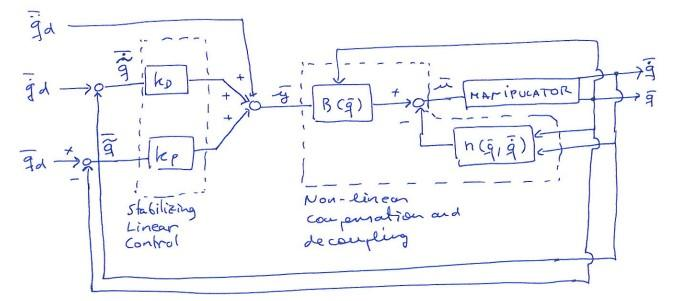

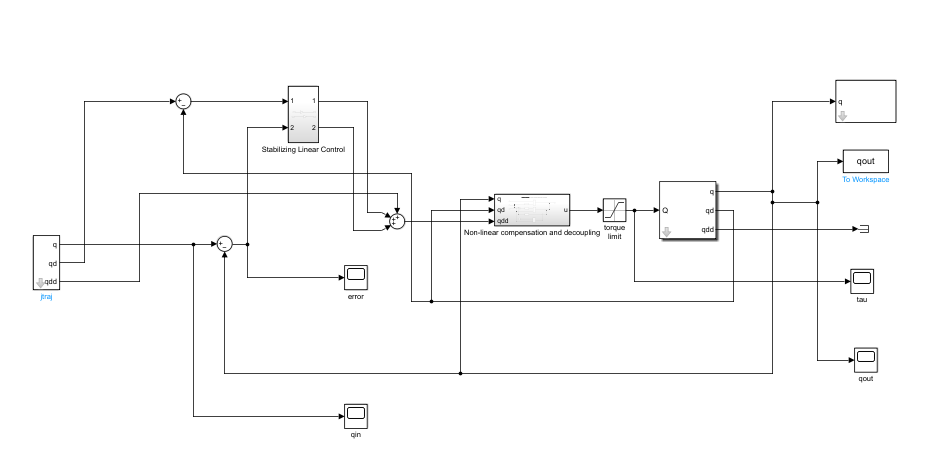

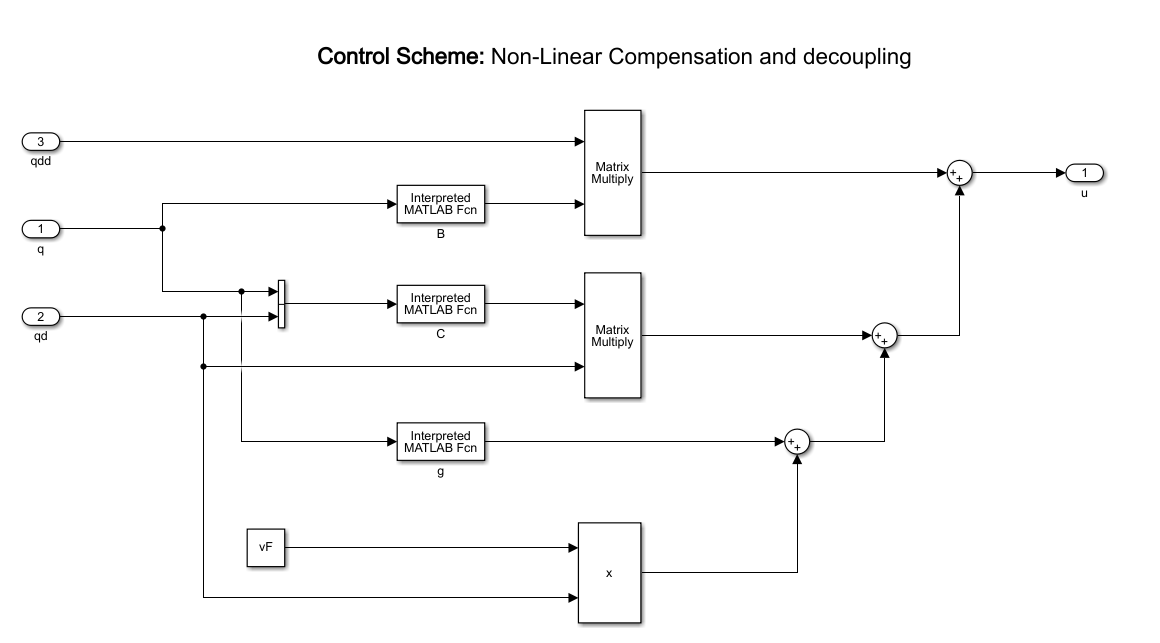

three_link_inverse_control
max_torques = [400 400 400]; % upper and lower limits for the saturator
min_torques = -[400 400 400];

%control parameters for Stabilizing Linear Control
KD=20; %  tuned for faster response.
KP=200; % tuned to not saturate the Torque

## 3. Make a variant of the previous control scheme, where only the dominant  terms are computed in order to lighten the computational load. Verify  that the performance is only slightly affected.

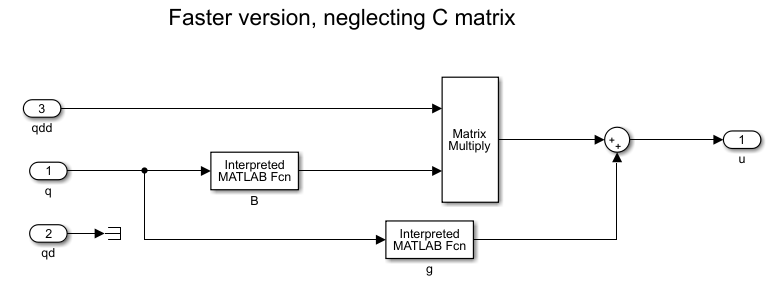

The next step is to analyte the differences between the two control strategies. The graphs are very similar to each other and both control systems are achieve the initial state of the robot [0 0 0] to its reference values [ pi/4 pi/4 pi/4].

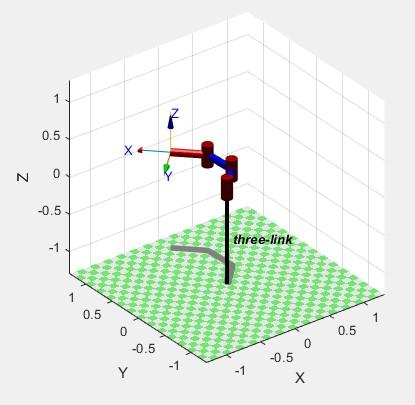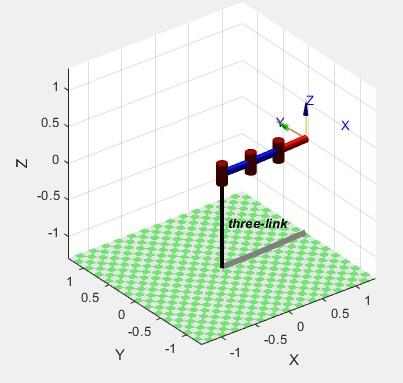

q1 q2 q3 (yellow blue and red respectively). The full model graph and then the quicker model will be shown.

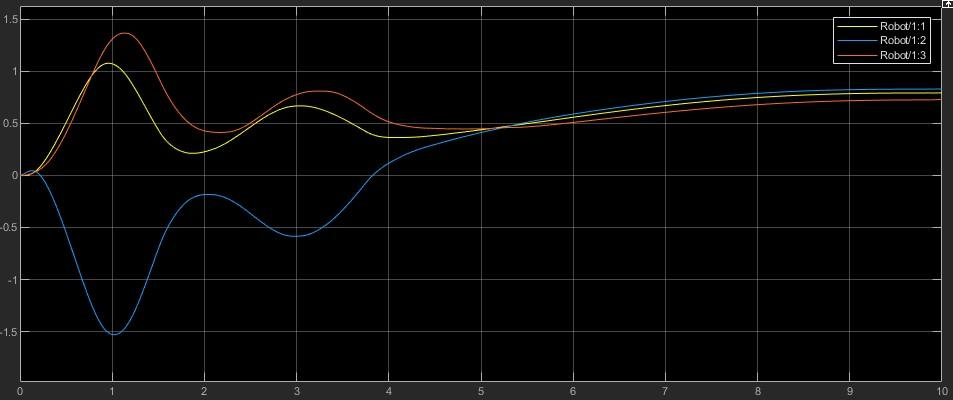

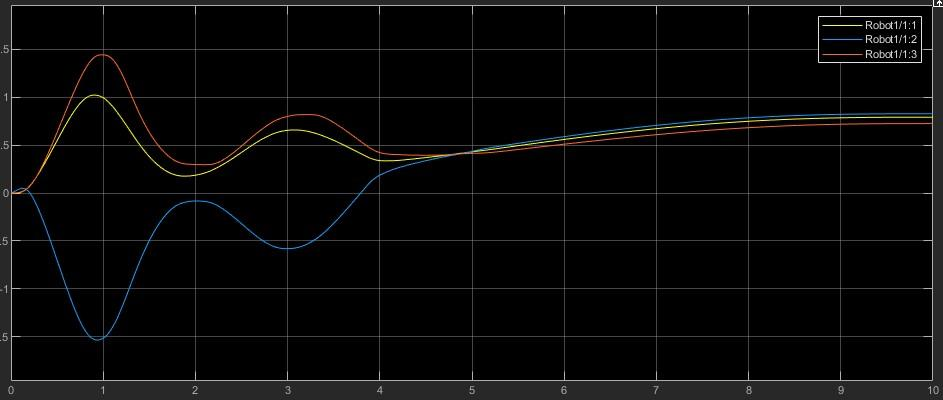

Errors relative to q1 q2 q3 (yellow blue and red respectively):

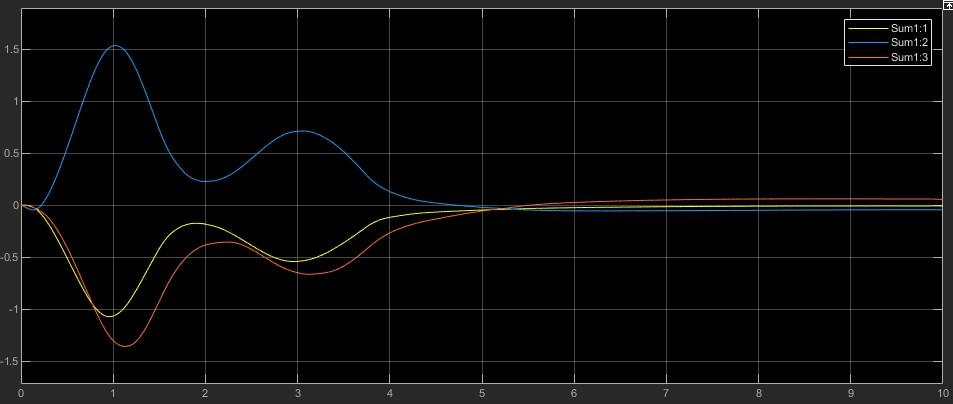

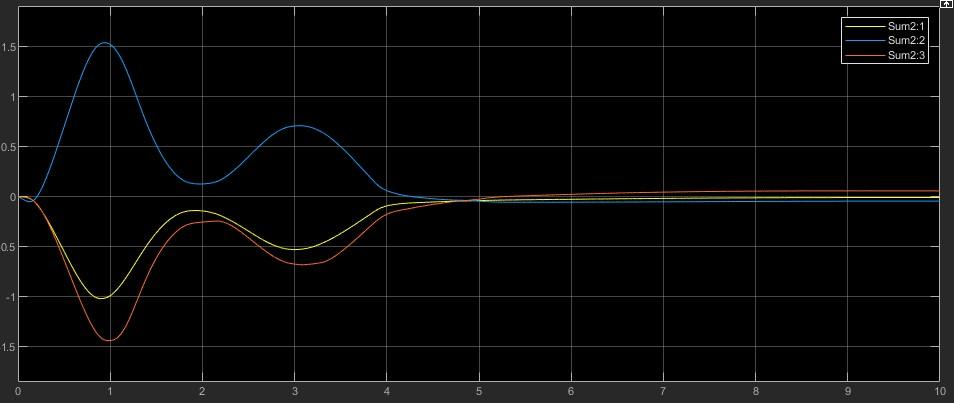

Torques of q1,q2 and q3:

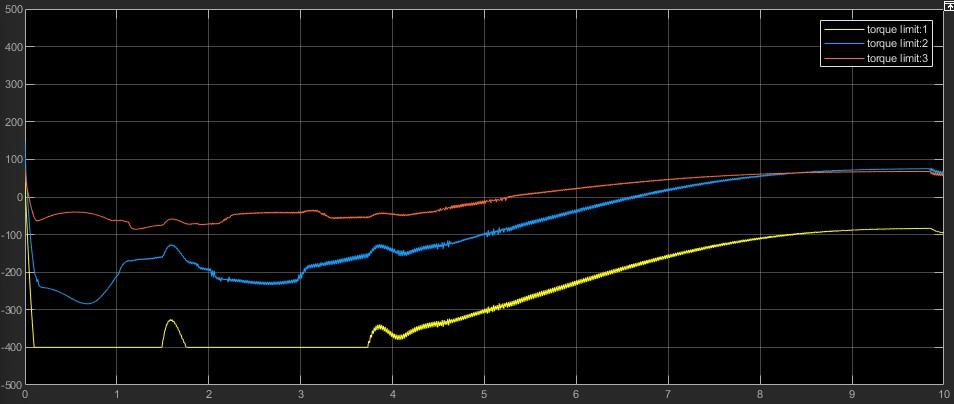

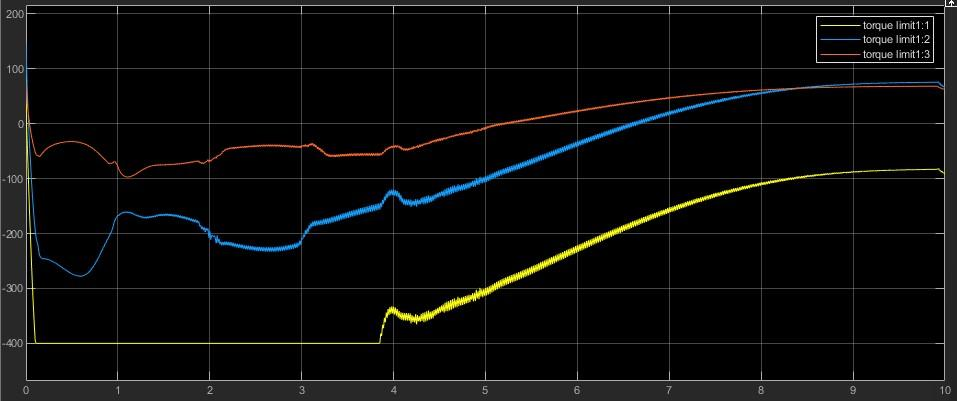

## Functions

function [coef_cijk] = cijk(bij, bik, bjk, qi, qj, qk)
    coef_cijk =(0.5*(diff(bij,qk) + diff(bik,qj)-diff(bjk,qi)));
end